clear all；clc；

一、

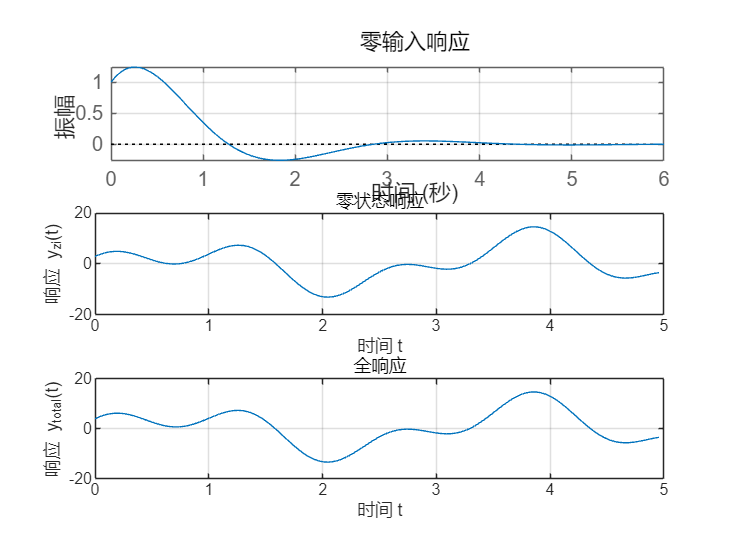

num=[3,20,10];
den=[1,2,5];
t=0:0.043479:5;
x=sin(2*t)+cos(5*t);
y_zs=lsim(num,den,x,t);
[a,b,c,d]=tf2ss(num,den);
sys=ss(a,b,c,d);
A=[1,-a(1,:);c(1),c(2),0;0,c(1),c(2)];
R=A\[0,2,1].';
figure(1);
subplot(3,1,1);
[y_zi, t_zi]=initial(sys,R(2:3));
initial(sys,R(2:3));
title('零输入响应');
grid on;

subplot(3,1,2);
plot(t,y_zs);
title('零状态响应');
xlabel('时间 t');
ylabel('响应 y_{zi}(t)');
grid on;

subplot(3,1,3);
plot(t,y_zs+y_zi);
title('全响应');
xlabel('时间 t');
ylabel('响应 y_{total}(t)');
grid on;

二、

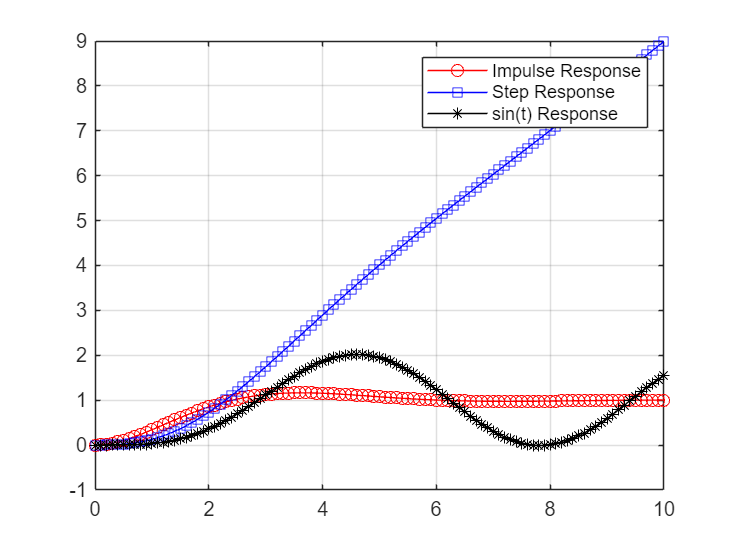

num=1;
den=[1,1,1,0];
t=0:0.1:10;
x=sin(t);
h1=impulse(num,den,t);
h2=step(num,den,t);
y=lsim(num,den,x,t);
figure(2);
plot(t,h1,'r-o');
hold on;
plot(t,h2, 'b-s');
plot(t,y, 'k-*');
legend('Impulse Response','Step Response','sin(t) Response');
grid on;
hold off;

三、

(1)

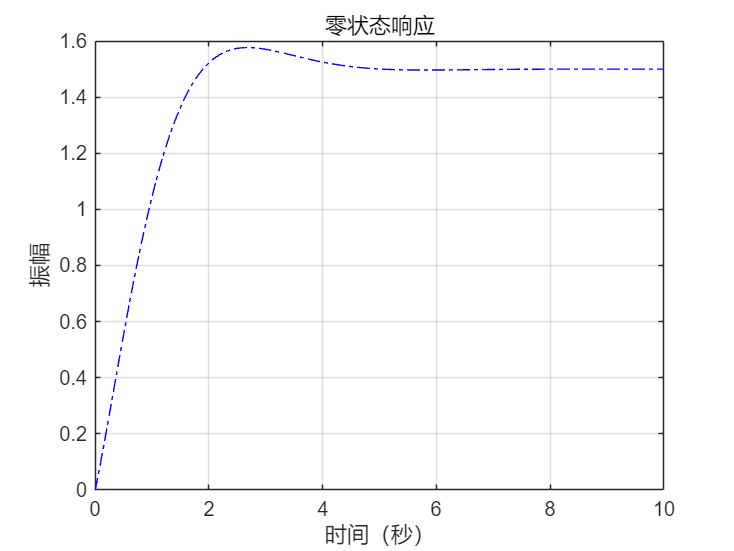

num=[1,3];
den=[1,2,2];
sys=tf(num,den);
t=0:0.01:10;
u=heaviside(t);
r=lsim(sys,u,t);
plot(t,r,'b-.');
xlabel('时间（秒）');
ylabel('振幅');
title('零状态响应');
grid on;

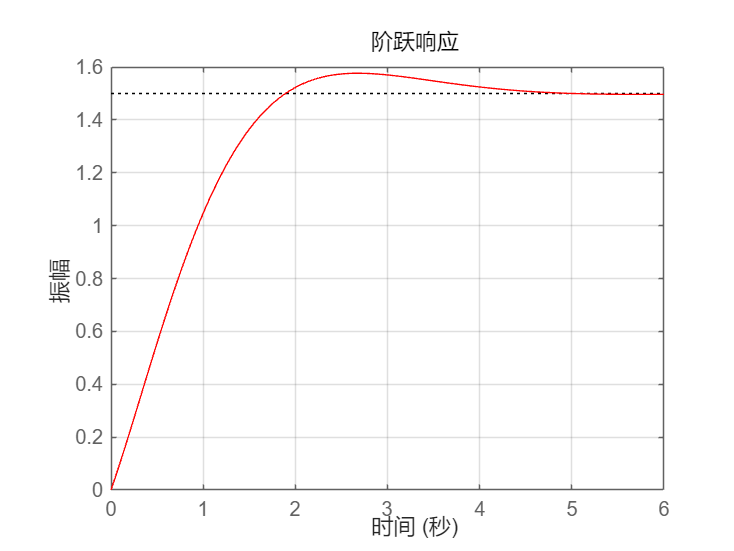

step(sys,'r-');
grid on;

四、

(1)

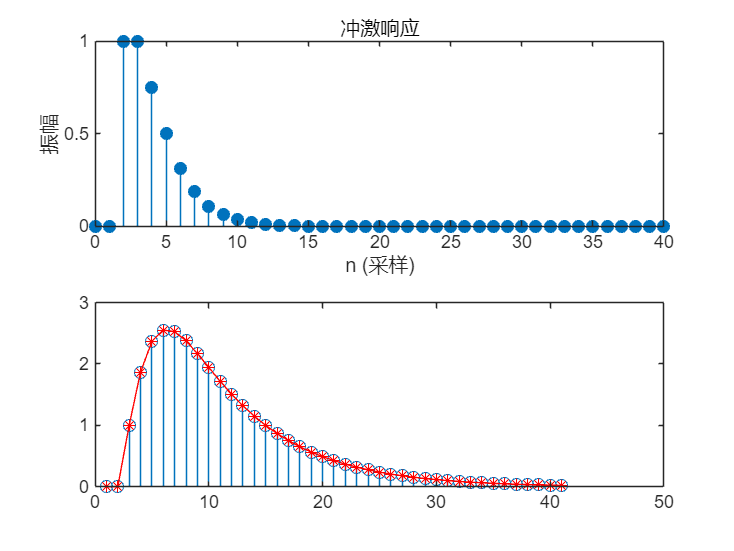

b=[0,0,1];
a=[1,-1,0.25];
n=0:40;
x=exp(-n/7);
y=filter(b,a,x);
aa=impz(b,a,n);
bb=conv(aa,x);
figure();
subplot(2,1,1);
impz(b,a,n);
subplot(2,1,2);
stem(y);
hold on;
plot(n+1,[bb(1:41)],'r-*');
hold off;

五、

num=[2,-0.3];
den=[1,-0.3,0.02];
z = roots([1, -0.1, -0.2]);
if all(abs(z) < 1)
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统稳定


x = [2, zeros(1, 7)];  

y = filter(num, den, x);

disp('系统的前8个输出值为:');

系统的前8个输出值为:


disp(y);

    4.0000    0.6000    0.1000    0.0180    0.0034    0.0007    0.0001    0.0000



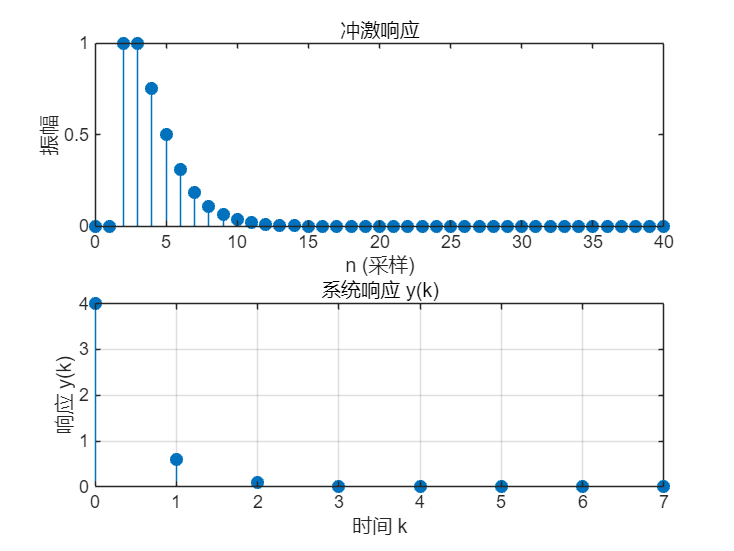


stem(0:7, y, 'filled');
title('系统响应 y(k)');
xlabel('时间 k');
ylabel('响应 y(k)');
grid on;